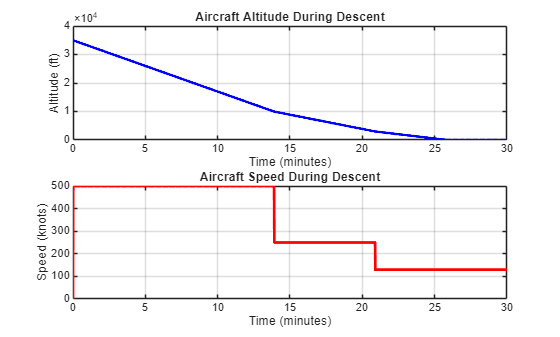

% Author: Christopher Bourjaili
% Module 2
% Project 12
% Title: Aircraft Descent Profile
%
% Summary of Code:
% - Simulates an aircraft descending from cruising altitude to landing.
% - Applies maximum and minimum speed constraints during descent.
% - Models three descent phases:
%     1. Steady descent
%     2. Leveling / reduced descent
%     3. Final approach
% - Calculates altitude and vertical speed over time.
% - Creates plots of altitude vs time and speed vs time.
%
% What I Learned:
% This project demonstrated how MATLAB can be used to simulate a real-world
% aerospace system using loops, conditionals, and arrays. I learned how
% operational constraints such as speed limits and changing descent rates
% affect the aircraft's altitude profile. I also practiced visualizing
% engineering data with graphs, making it easier to interpret each phase
% of the descent process.


clc
clear
close all

h0 = 35000;          
hf = 0;              

t_total = 1800;      
dt = 1;              
t = 0:dt:t_total;    

n = length(t);

v_max = 500;         
v_min = 130;         

altitude = zeros(1,n);
speed = zeros(1,n);
vspeed = zeros(1,n);   

altitude(1) = h0;

for i = 2:n
    
    if altitude(i-1) > 10000
        speed(i) = v_max;
        vspeed(i) = -1800;      
        
    elseif altitude(i-1) > 3000
        speed(i) = 250;
        vspeed(i) = -1000;
        
    else
        speed(i) = v_min;
        vspeed(i) = -600;
    end
    
    altitude(i) = altitude(i-1) + vspeed(i)*dt/60;
    
    if altitude(i) <= hf
        altitude(i) = hf;
        speed(i:end) = v_min;
        vspeed(i:end) = 0;
        break
    end
end

figure

subplot(2,1,1)
plot(t/60, altitude,'b','LineWidth',2)
grid on
xlabel('Time (minutes)')
ylabel('Altitude (ft)')
title('Aircraft Altitude During Descent')

subplot(2,1,2)
plot(t/60, speed,'r','LineWidth',2)
grid on
xlabel('Time (minutes)')
ylabel('Speed (knots)')
title('Aircraft Speed During Descent')


disp('Descent Phases:')

Descent Phases:


disp('1. Steady descent above 10,000 ft at max speed.')

1. Steady descent above 10,000 ft at max speed.


disp('2. Reduced speed and descent rate below 10,000 ft.')

2. Reduced speed and descent rate below 10,000 ft.


disp('3. Final approach uses minimum safe speed and shallow descent.')

3. Final approach uses minimum safe speed and shallow descent.


disp('Speed constraints control how quickly altitude can be lost safely.')

Speed constraints control how quickly altitude can be lost safely.
